# Sampling

Load the photo.

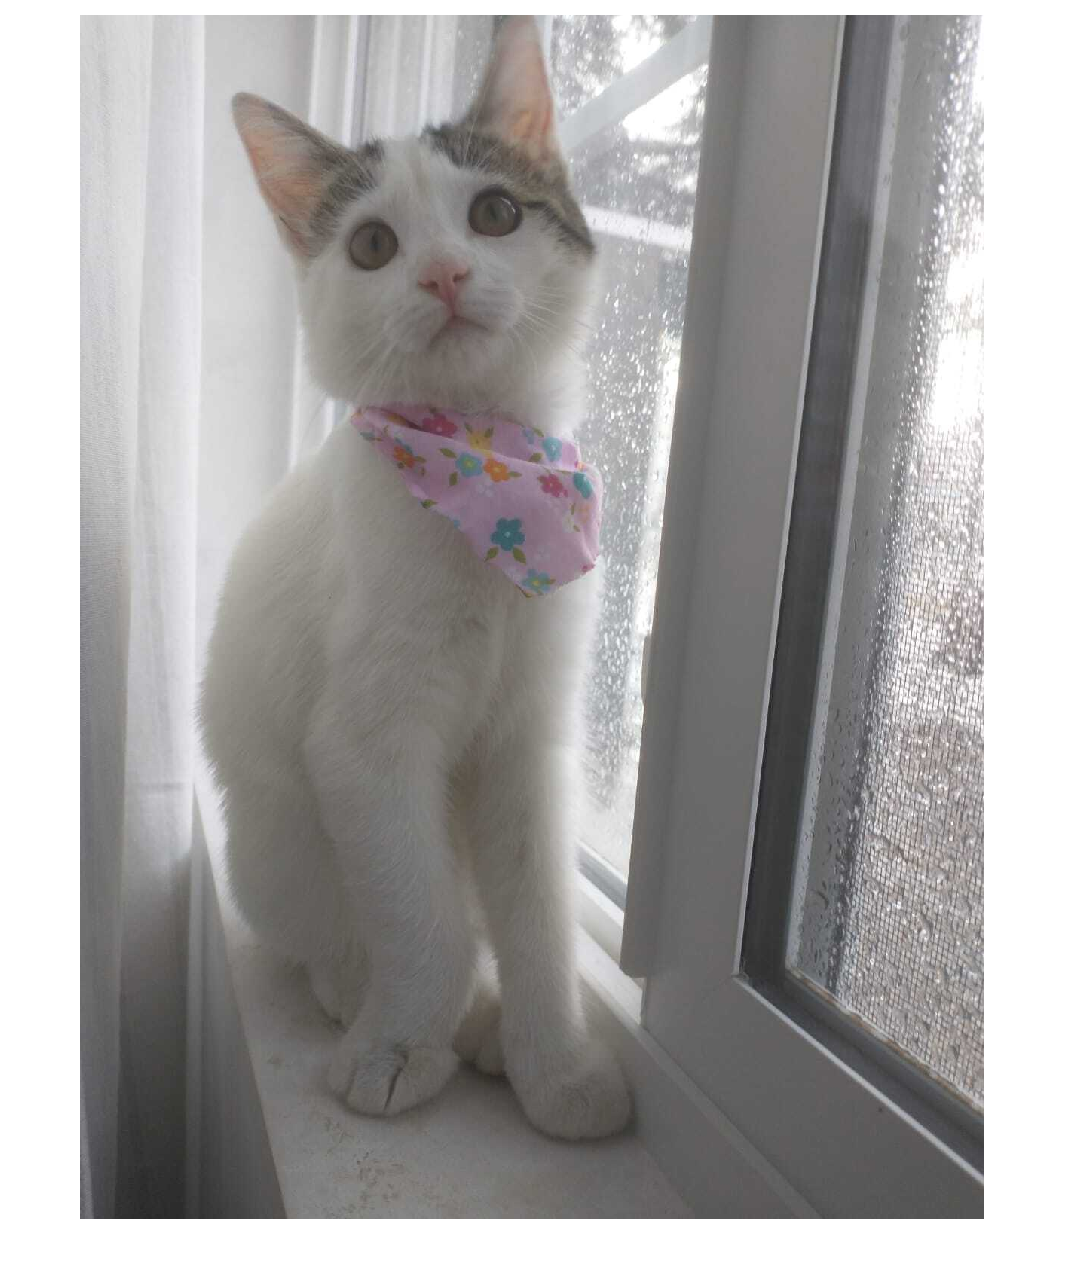

luca=imread('luca.jfif');
figure(1);
imshow(luca)

gray scale

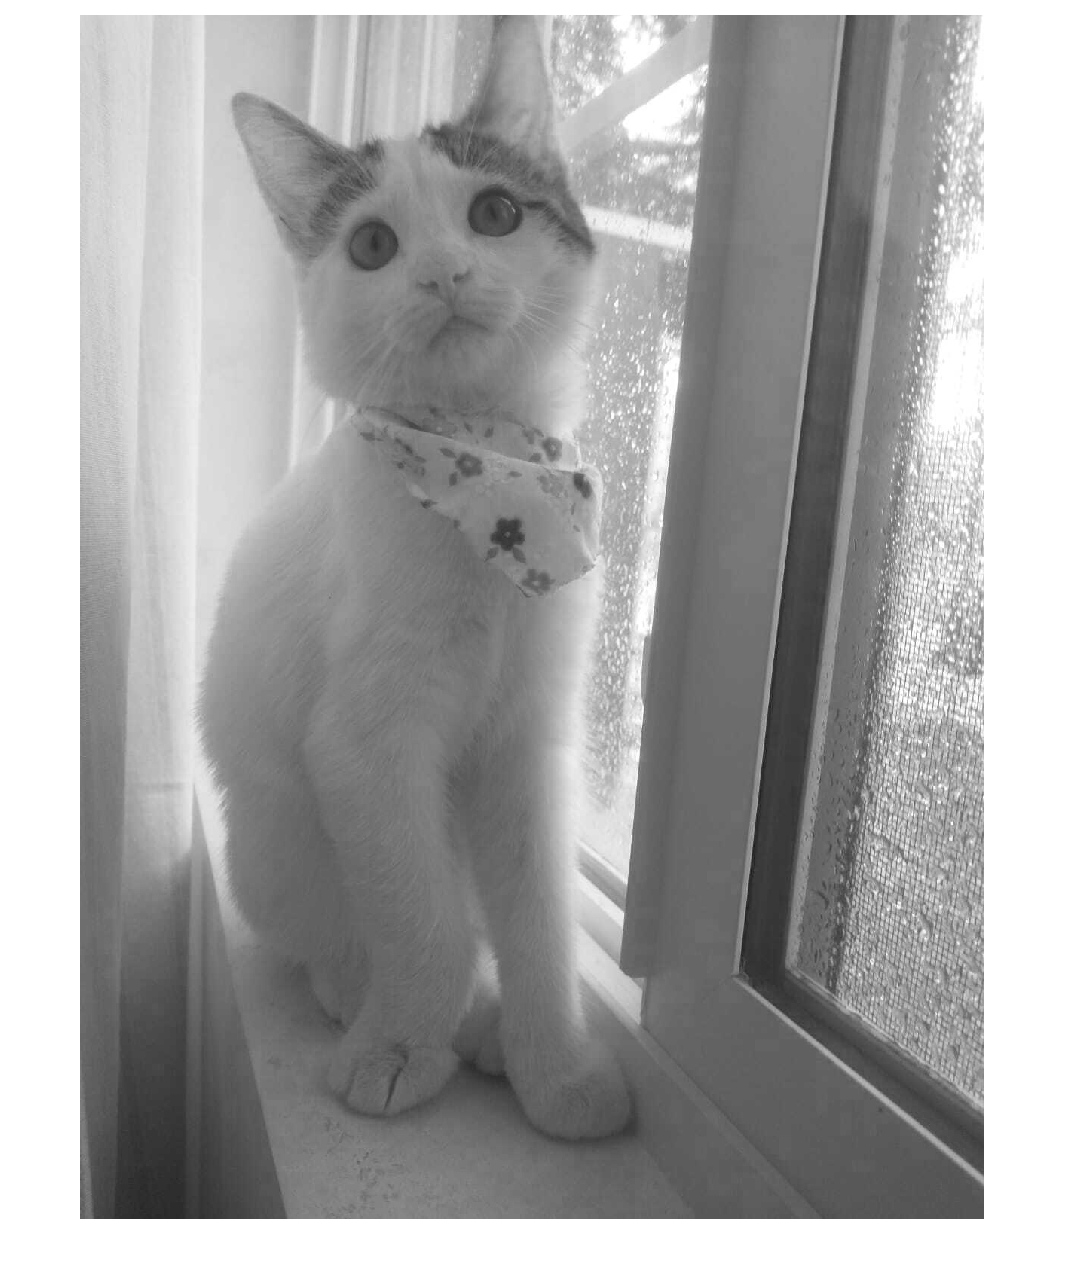

red = luca(:,:,1);
imshow(red)

# Pyramid Representation

In this section we present the pyramid representation of the image using nearest neighbor, bilinear filtering and max pooling filtering. 

## Downsampling - nearest neighbor

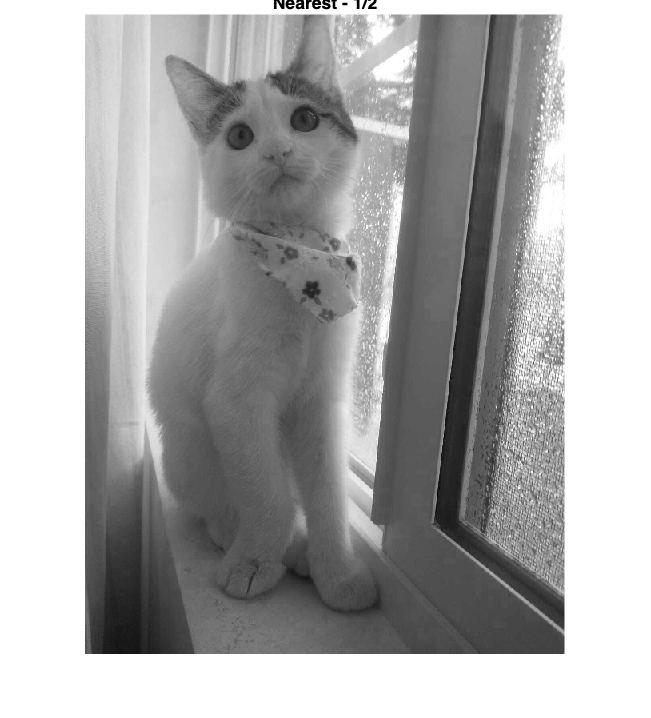

f1=imresize(red,0.5,"nearest");
imshow(f1,[])
title('Nearest - 1/2');

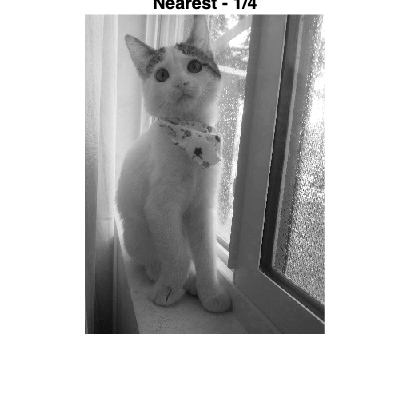


f2=imresize(f1,0.5,"nearest");
imshow(f2,[])
title('Nearest - 1/4');

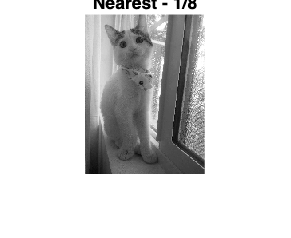


f3=imresize(f2,0.5,"nearest");
imshow(f3,[])
title('Nearest - 1/8');


f4=imresize(f3,0.5,"nearest");

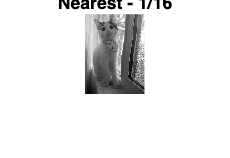

imshow(f4,[])
title('Nearest - 1/16');

## Downsampling - bilinear

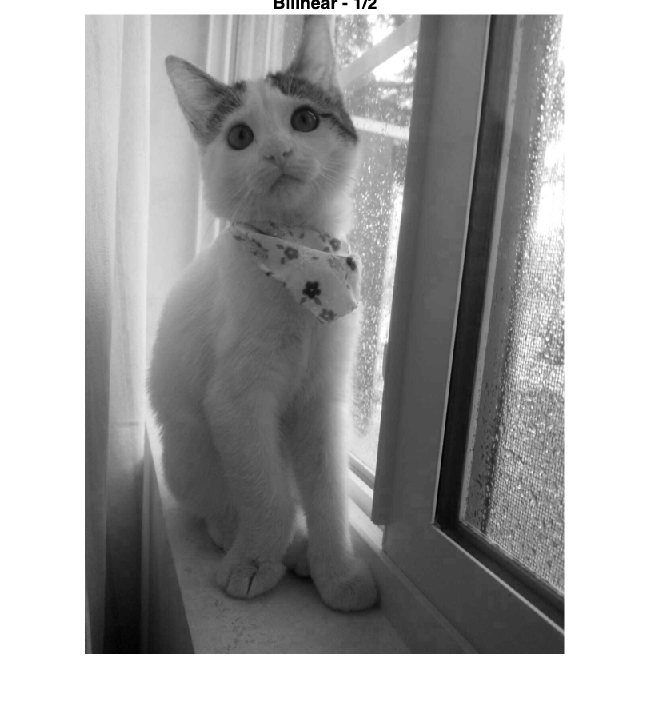

f1_bi=imresize(red,0.5,"bilinear");
imshow(f1_bi,[])
title('Bilinear - 1/2');

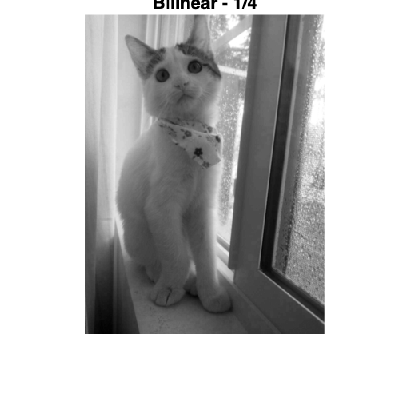


f2_bi=imresize(f1_bi,0.5,"bilinear");
imshow(f2_bi,[])
title('Bilinear - 1/4');

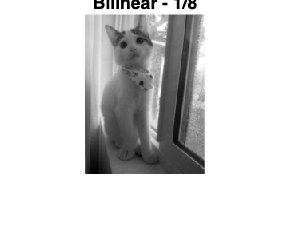


f3_bi=imresize(f2_bi,0.5,"bilinear");
imshow(f3_bi,[])
title('Bilinear - 1/8');

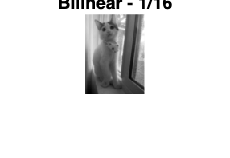


f4_bi=imresize(f3_bi,0.5,"bilinear");
imshow(f4_bi,[])
title('Bilinear - 1/16');

## Downsamplin - maxpooling

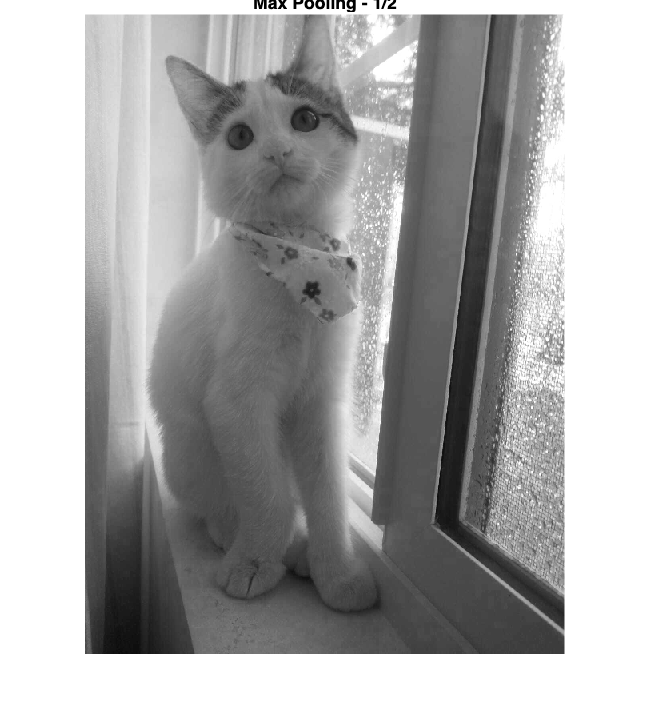

sz = size(red);
xcor = int16(linspace(1,sz(1),sz(1)));
ycor = int16(linspace(1,sz(2),sz(2)));

%  Define the max pooling function
maxPool = @(img) blockproc(img, [2 2], @(block) max(block.data(:)));

% Apply max pooling to the image in each step
f1_m = maxPool(red);
imshow(f1_m, []);
title('Max Pooling - 1/2');

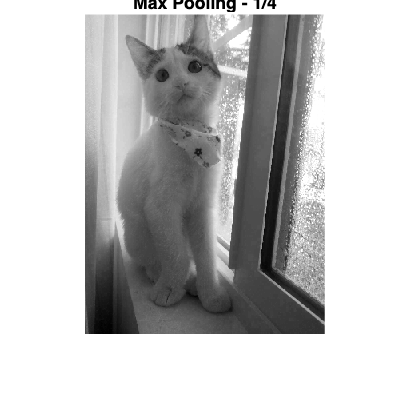


f2_m = maxPool(f1_m);
imshow(f2_m, []);
title('Max Pooling - 1/4');

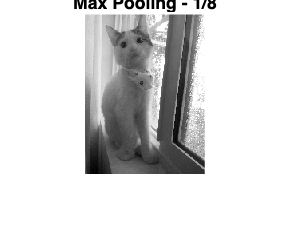


f3_m = maxPool(f2_m);
imshow(f3_m, []);
title('Max Pooling - 1/8');

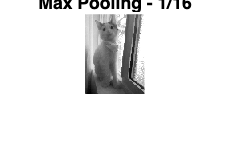


f4_m = maxPool(f3_m);
imshow(f4_m, []);
title('Max Pooling - 1/16');

Also, we apply decimation followed by downsampling (using the nearest neighbor and bilinear methods) to see the impact

## Decimation - nearest

lowpass=fspecial("gaussian",3,1)

lowpass =     0.0751    0.1238    0.0751
    0.1238    0.2042    0.1238
    0.0751    0.1238    0.0751


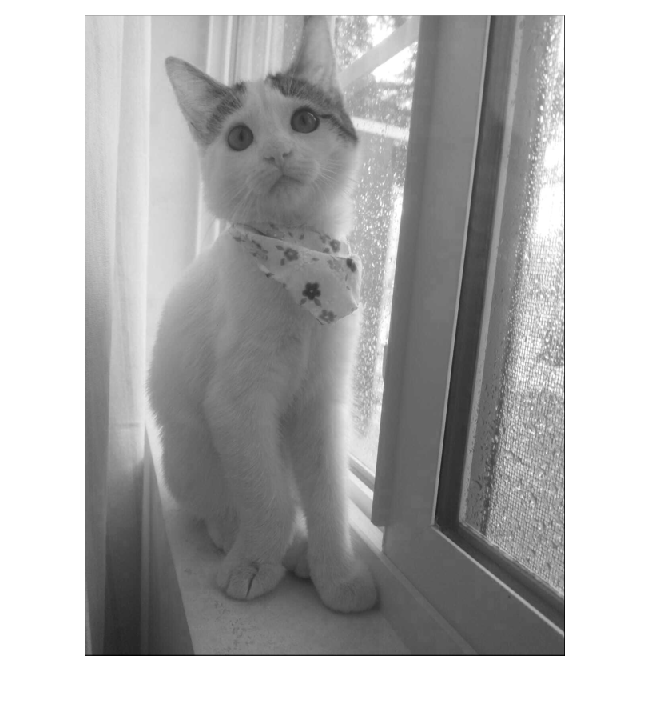

f1_nd=imresize(conv2(red,lowpass),0.5,"nearest");
imshow(f1_nd,[])

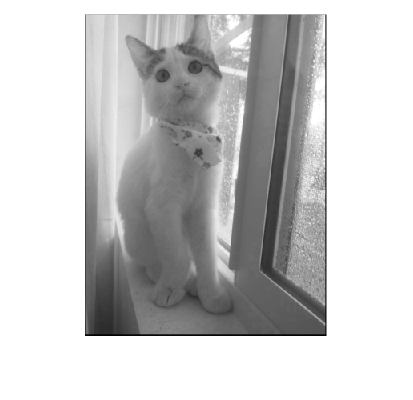

f2_nd=imresize(conv2(f1_nd,lowpass),0.5,"nearest");
imshow(f2_nd,[])

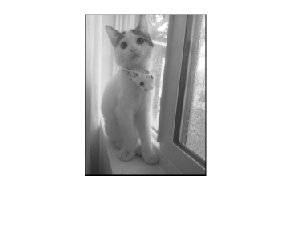

f3_nd=imresize(conv2(f2_nd,lowpass),0.5,"nearest");
imshow(f3_nd,[])

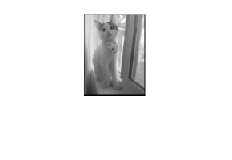

f4_nd=imresize(conv2(f3_nd,lowpass),0.5,"nearest");
imshow(f4_nd,[])

## Decimation - bilinear

lowpass=fspecial("gaussian",3,1)

lowpass =     0.0751    0.1238    0.0751
    0.1238    0.2042    0.1238
    0.0751    0.1238    0.0751


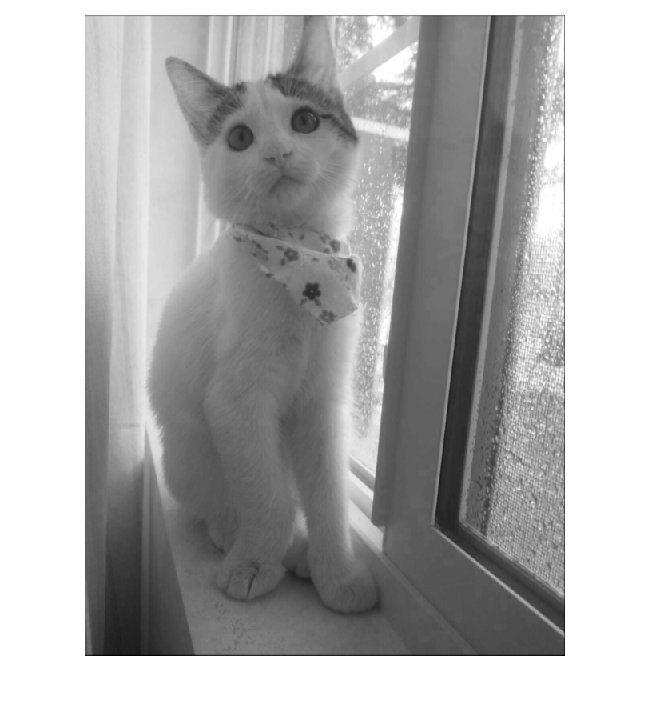

f1_bid=imresize(conv2(red,lowpass),0.5,"bilinear");
imshow(f1_bid,[])

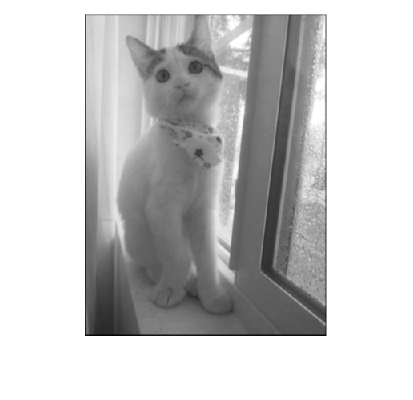

f2_bid=imresize(conv2(f1_bid,lowpass),0.5,"bilinear");
imshow(f2_bid,[])

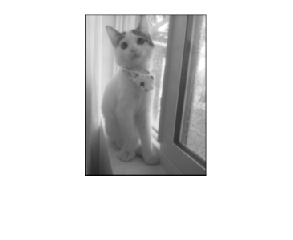

f3_bid=imresize(conv2(f2_bid,lowpass),0.5,"bilinear");
imshow(f3_bid,[])

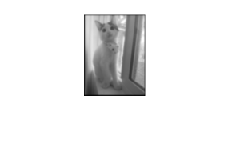

f4_bid=imresize(conv2(f3_bid,lowpass),0.5,"bilinear");
imshow(f4_bid,[])

# Up sample to the original size

In this section we use the 1/16 representation (using the three different methods used for downsampling, and the two images where we used decimation followed by downsampling) and we up sample each image using bilinear interpolation and SINC interpolation.

## Upsampling - bilinear 

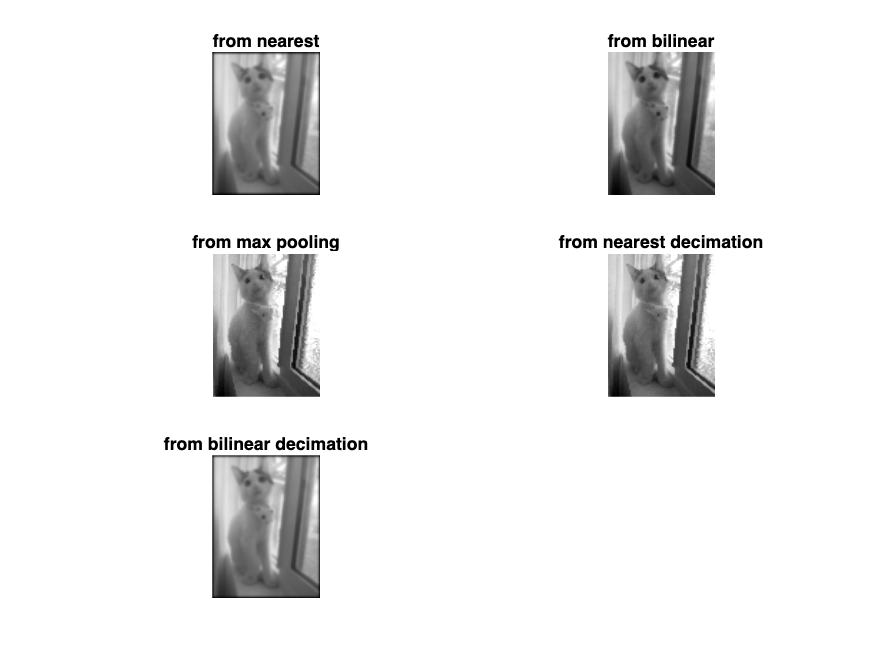

upimage_nn = imresize(f4,2^4,"bilinear");
figure();
subplot(3,2,1)
imshow(upimage,[])
title("from nearest")

upimage = imresize(f4_bi,2^4,"bilinear");
subplot(3,2,2)
imshow(upimage,[])
title("from bilinear")

upimage = imresize(f4_m,2^4,"bilinear");
subplot(3,2,3)
imshow(upimage,[])
title("from max pooling")

upimage_nn = imresize(f4_nd,2^4,"bilinear");
subplot(3,2,4)
imshow(upimage,[])
title("from nearest decimation")

upimage = imresize(f4_bid,2^4,"bilinear");
subplot(3,2,5)
imshow(upimage,[])
title("from bilinear decimation")

## SINC interpolation

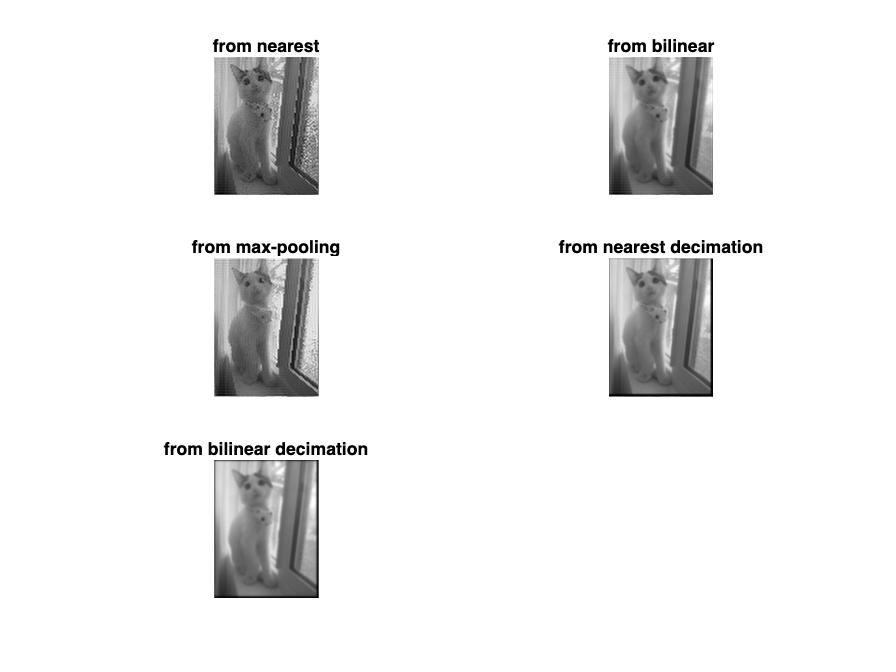

figure();
osize=size(upimage);
F = fft2(f4);
upsinc = ifft2(fftshift(F),osize(1),osize(2));
subplot(3,2,1)
imshow(abs(upsinc),[])
title("from nearest")


F = fft2(f4_bi);
upsinc = ifft2(fftshift(F),osize(1),osize(2));
subplot(3,2,2)
imshow(abs(upsinc),[])
title("from bilinear")

F = fft2(f4_m);
upsinc = ifft2(fftshift(F),osize(1),osize(2));
subplot(3,2,3)
imshow(abs(upsinc),[])
title("from max-pooling")

F = fft2(f4_nd);
upsinc = ifft2(fftshift(F),osize(1),osize(2));
subplot(3,2,4)
imshow(abs(upsinc),[])
title("from nearest decimation")


F = fft2(f4_bid);
upsinc = ifft2(fftshift(F),osize(1),osize(2));
subplot(3,2,5)
imshow(abs(upsinc),[])
title("from bilinear decimation")